# Exercise 1: Antenna Array Analysis with Custom Radiation Pattern

Number of steps: 4 

Expected completion time: 10 minutes

In this section,  an antenna array with a custom antenna radiation pattern is created and the array's response pattern is analyzed. Custom element pattern can be obtained either from measurements or from simulations. 

## Import the Radiation Pattern

Import a custom radiation pattern obtained from measurements or simulations (e.g. HFSS). The simulated radiation pattern is represented as an *M*-by-3 matrix where the first column represents the azimuth angle $\phi$, the second column represents the elevation angle $\theta$, and the third column represents the radiation pattern in dB. The value of $\phi$ is between $0^\circ$ and $360^\circ$ and the value of $\theta$ is between $0^\circ$ and $180^\circ$.

We will use helper function (helperPatternImport.m) to read .csv file. The cardioid-shaped antenna pattern is simulated in the $\phi$ - $\theta$ convention and is saved in a `.csv` file. The helper function `helperPatternImport` reads the custom `.csv` file and reformats its contents into a two-dimensional matrix in $\phi$ and $\theta$.

% use helper function (helperPatternImport.m) to read .csv file and
% reformat into 2-D Matrix.
[pattern_phitheta,phi,theta] = helperPatternImport;

Verify MATLAB workspace variables: phi, theta and pattern_phitheta.

## Create Custom Antenna Element 

The phi-theta pattern can now be used to form a custom antenna element. Assume that this antenna operates between 1 and 1.25 GHz.

freqVector  = [1 1.25].*1e9;        % Frequency range for element pattern 

%--------------------------
% ADD CODE HERE
% Hint: use phased.CustomAntennaElement function to create antenna element using imported
% data. Type 'doc phased.CustomAntennaElement' into the command line interface 
% for more information. 
% Supply the FrequencyVector (freqVec), PhiAngles (phi), ThetaAngles
% (theta), MagnitudePattern (pattern_phitheta), PhasePattern (zeros(size(pattern_phitheta))).
% Name the output object 'antenna'.  

% ------------------------------
antenna     = phased.CustomAntennaElement('FrequencyVector',freqVector, ...
                              'PatternCoordinateSystem','phi-theta',...
                              'PhiAngles',phi,...
                              'ThetaAngles',theta,...
                              'MagnitudePattern',pattern_phitheta,...
                              'PhasePattern',zeros(size(pattern_phitheta)));

### Plot Antenna Element Radiation pattern

To verify that the pattern has been correctly imported, plot the response of the custom antenna element at selected frequency value. 

fmax = freqVector(end);  % display Radiation pattern at f=fmax 
%---------------------------------------------------------------------------------------------------
% ADD CODE HERE
% Hint: use 'pattern' function to plot radiation pattern for 'antenna' element.   Type 'doc
% pattern' into the command line interface for more information.  
% Supply fmax as frequency for plot, for 'Type' parameter specify 'powerdb'

%--------------------------------
pattern(antenna,fmax,'Type','powerdb')

Notice that the main beam points to $0^\circ$ azimuth and $90^\circ$ elevation, the custom pattern with main beam along z-axis is imported without any rotation.

## Construct Antenna Array: Uniform Rectangular Array 

Construct a 64-element antenna array (URA) whose elements reside on a 8-by-8 rectangular grid. To ensure that no grating lobes appear, elements are spaced at one-half wavelength at the highest operating frequency. 

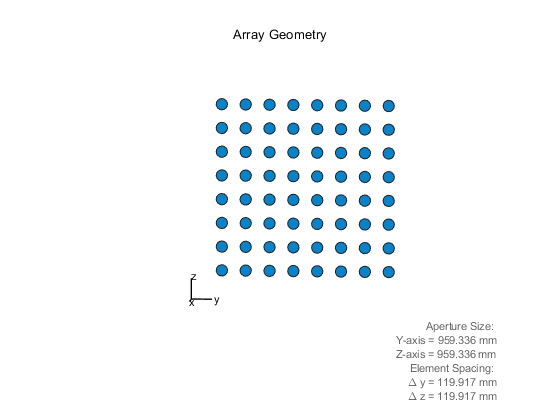

c = physconst('LightSpeed');
lambda = c/fmax;

%--------------------------
% ADD CODE HERE
% Hint: use phased.URA function to create an array using antenna element
% created in a previous step. Type 'doc phased.URA' into the command line interface 
% for more information. 
% Supply the Element (Element), Size (8), ElementSpacing (lambda/2).
% Name the output object 'array'.  
% Verify 'array' object in your workspace

% ------------------------------
array = phased.URA('Element',antenna,'Size',8,'ElementSpacing',lambda/2)

array =   phased.URA with properties:

           Element: [1×1 phased.CustomAntennaElement]
              Size: [8 8]
    ElementSpacing: [0.1199 0.1199]
           Lattice: 'Rectangular'
       ArrayNormal: 'x'
             Taper: 1


## Plot Array radiation pattern in 3D

Use Phased Array System toolbox 'pattern' function to visualize created array Rdiation pattern. 

%---------------------------------------------------------------------------------------------------
% ADD CODE HERE
% Hint: use 'pattern' function to plot array radiation pattern.   Type 'doc
% pattern' into the command line interface for more information.  
% Supply fmax as frequency for a plot, 'PropagationSpeed' (c) and for
% 'Type' ('powerdb')

%--------------------------------
pattern(array,fmax,'PropagationSpeed',c,'Type','powerdb')

### Plot Array radiation pattern in u-v space

The total radiation pattern of the resulting antenna array is plotted below in *u-v* space. The pattern is a combination of both the element pattern and the array factor.


figure(1)
pattern(array,fmax,'PropagationSpeed',c,'Type','powerdb',...
    'CoordinateSystem','UV');


One can also easily examine the *u*-cut of the pattern as shown below.

figure(2)
pattern(array,fmax,-1:0.01:1,0,'PropagationSpeed',c, ...
    'CoordinateSystem','uv','Type','powerdb')
axis([-1 1 -50 0]);

## Exercise Question 

- Why use a "Custom Radiation Pattern"?

- Array Design Choices: are you using **Uniform Rectangular Array (URA)** or different geometries

-  Visualizing the array radiation pattern in **3D** versus in **u-v space**? When is each visualization most useful?

## Summary

This exercise shows how to construct and analyze an antenna array using a custom antenna pattern. The pattern can be generated using full-wave modeling simulation software with the $\phi$ - $\theta$ convention. The pattern can then be used to form a custom antenna element. 